clear; close all; clc;

%% Load Data
trainData = readtable('DailyDelhiClimateTrain.csv');
testData  = readtable('DailyDelhiClimateTest.csv');
trainData.date = datetime(trainData.date, "InputFormat", "yyyy-MM-dd");
testData.date  = datetime(testData.date, "InputFormat", "yyyy-MM-dd");

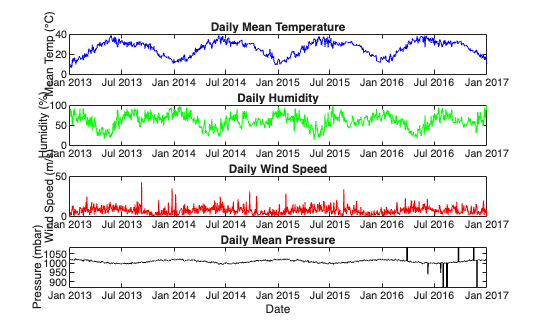

%% Visualizations
figure;

subplot(4,1,1);
plot(trainData.date, trainData.meantemp, '-b');
ylabel('Mean Temp (°C)'); 
title('Daily Mean Temperature');

subplot(4,1,2);
plot(trainData.date, trainData.humidity, '-g');
ylabel('Humidity (%)'); 
title('Daily Humidity');

subplot(4,1,3);
plot(trainData.date, trainData.wind_speed, '-r');
ylabel('Wind Speed (m/s)'); 
title('Daily Wind Speed');

subplot(4,1,4);
plot(trainData.date, trainData.meanpressure, '-k');
ylabel('Pressure (mbar)'); 
xlabel('Date');
mu = mean(trainData.meanpressure);
sigma = std(trainData.meanpressure);
ylim([870, 1084]); % World records, outliers supposed error of measure (7 bar obviously imposible)
title('Daily Mean Pressure');


summary(trainData(:, 2:end));


1462×4 table

Variables:

    meantemp: double
    humidity: double
    wind_speed: double
    meanpressure: double

Statistics for applicable variables:

                    NumMissing        Min            Median             Max               Mean             Std     

    meantemp            0                 6           27.7143           38.7143           25.4955          7.3481  
    humidity            0           13.4286           62.6250               100           60.7717         16.7697  
    wind_speed          0                 0            6.2217           42.2200            6.8022          4.5616  
    meanpressure        0           -3.0417        1.0086e+03        7.6793e+03        1.0111e+03        180.2317  



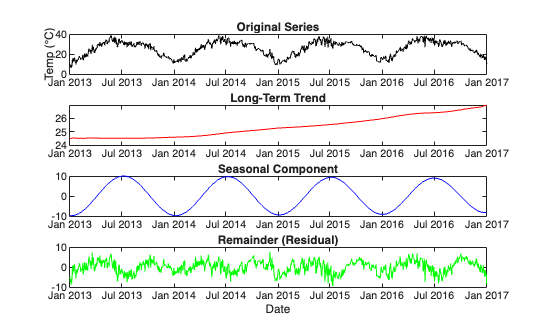

%% Time-Series Decomposition

TT = timetable(trainData.date, trainData.meantemp);
TT.Properties.VariableNames = ["meantemp"];
decomp = trenddecomp(TT);

trend     = decomp.meantemp_LongTerm;
seasonal  = decomp.meantemp_Seasonal;
residual  = decomp.meantemp_Remainder;

figure;

subplot(4,1,1);
plot(TT.Time, TT.meantemp, 'k');
title('Original Series'); ylabel('Temp (°C)');

subplot(4,1,2);
plot(TT.Time, trend, 'r');
title('Long-Term Trend');

subplot(4,1,3);
plot(TT.Time, seasonal, 'b');
title('Seasonal Component');

subplot(4,1,4);
plot(TT.Time, residual, 'g');
title('Remainder (Residual)');
xlabel('Date');

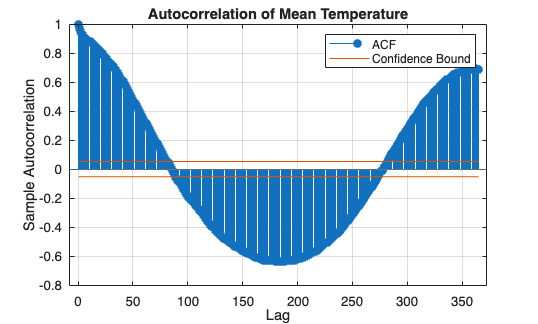

%% Autocorrelation Analysis
y = trainData.meantemp;
figure;
autocorr(y, 'Numlags', 365);
title('Autocorrelation of Mean Temperature');

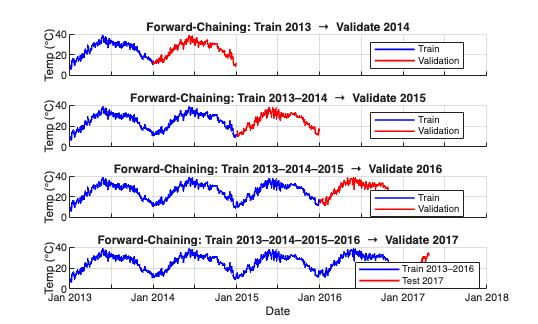

%% Forward-chaining by year (aligned x-axis 2013–2018)

yearsTrain = year(trainData.date);
yearsTest  = year(testData.date);

figure;

% four stage
splits = {
    [2013], [2014];
    [2013 2014], [2015];
    [2013 2014 2015], [2016];
    [2013 2014 2015 2016], [2017]
};

for i = 1:4
    subplot(4,1,i); hold on;
    
    trYears  = splits{i,1};
    valYears = splits{i,2};
    
    if valYears == 2017
        % last fold
        plot(trainData.date(ismember(yearsTrain,trYears)), trainData.meantemp(ismember(yearsTrain,trYears)), 'b', 'LineWidth', 1.2);
        plot(testData.date, testData.meantemp, 'r', 'LineWidth', 1.2);
    else
        plot(trainData.date(ismember(yearsTrain,trYears)), trainData.meantemp(ismember(yearsTrain,trYears)), 'b', 'LineWidth', 1.2);
        plot(trainData.date(yearsTrain==valYears), trainData.meantemp(yearsTrain==valYears), 'r', 'LineWidth', 1.2);
    end
    
    xlim([datetime(2013,1,1), datetime(2018,1,1)]);
    
    ylabel('Temp (°C)');
    grid on;
    
    if i == 4
        xlabel('Date');
    else
        set(gca, 'XTickLabel', []);
    end
    
    titleStr = sprintf('Forward-Chaining: Train %s  →  Validate %s', ...
        strjoin(string(trYears), '–'), string(valYears));
    title(titleStr);
    
    if valYears == 2017
        legend({'Train 2013–2016','Test 2017'}, 'Location','best');
    else
        legend({'Train','Validation'}, 'Location','best');
    end
end